clear all; close all;

%% Definició de les tensions
w = 2*pi*50;
t = 0:0.04/200:0.04;

va = 0.5*sin(w*t)%+0.1*sin(-w*t);

va =          0    0.0314    0.0627    0.0937    0.1243    0.1545    0.1841    0.2129    0.2409    0.2679    0.2939    0.3187    0.3423    0.3645    0.3853    0.4045    0.4222    0.4382    0.4524    0.4649    0.4755    0.4843    0.4911    0.4961    0.4990    0.5000    0.4990    0.4961    0.4911    0.4843    0.4755    0.4649    0.4524    0.4382    0.4222    0.4045    0.3853    0.3645    0.3423    0.3187    0.2939    0.2679    0.2409    0.2129    0.1841    0.1545    0.1243    0.0937    0.0627    0.0314


vb = sin(w*t - 2*pi/3)%+ 0.1*sin(-w*t - 2*pi/3);

vb =    -0.8660   -0.8957   -0.9219   -0.9444   -0.9632   -0.9781   -0.9893   -0.9965   -0.9998   -0.9991   -0.9945   -0.9860   -0.9736   -0.9573   -0.9373   -0.9135   -0.8862   -0.8554   -0.8211   -0.7837   -0.7431   -0.6997   -0.6534   -0.6046   -0.5534   -0.5000   -0.4446   -0.3875   -0.3289   -0.2689   -0.2079   -0.1461   -0.0837   -0.0209    0.0419    0.1045    0.1668    0.2284    0.2890    0.3486    0.4067    0.4633    0.5180    0.5707    0.6211    0.6691    0.7145    0.7570    0.7965    0.8329


vc = sin(w*t + 2*pi/3)%+0.1*sin(-w*t + 2*pi/3);

vc =     0.8660    0.8329    0.7965    0.7570    0.7145    0.6691    0.6211    0.5707    0.5180    0.4633    0.4067    0.3486    0.2890    0.2284    0.1668    0.1045    0.0419   -0.0209   -0.0837   -0.1461   -0.2079   -0.2689   -0.3289   -0.3875   -0.4446   -0.5000   -0.5534   -0.6046   -0.6534   -0.6997   -0.7431   -0.7837   -0.8211   -0.8554   -0.8862   -0.9135   -0.9373   -0.9573   -0.9736   -0.9860   -0.9945   -0.9991   -0.9998   -0.9965   -0.9893   -0.9781   -0.9632   -0.9444   -0.9219   -0.8957


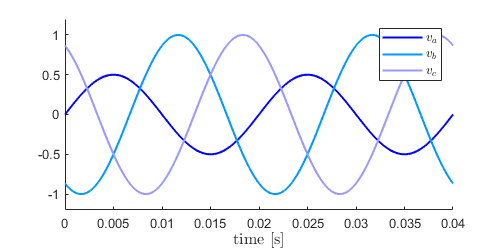

% va = rand * 1.1 * sin(w*t+rand*360);% + rand * 0.5 * sin(3*(w*t+rand*360)) + rand * 0.25 * sin(5*(w*t+rand*360));
% vb = rand * 1.1 * sin(w*t+rand*360);% + rand * 0.5 * sin(3*(w*t+rand*360)) + rand * 0.25 * sin(5*(w*t+rand*360));
% vc = rand * 1.1 * sin(w*t+rand*360);% + rand * 0.5 * sin(3*(w*t+rand*360)) + rand * 0.25 * sin(5*(w*t+rand*360));

%% Plot funcions temporals abc
f1 = figure(1);
set(f1, 'Position', [50 500 500 250]);
hold on;
plot(t,va,'LineWidth',1.5,'Color',[0 0 1]);
plot(t,vb,'LineWidth',1.5,'Color',[0 0.6 1]);
plot(t,vc,'LineWidth',1.5,'Color',[0.6 0.6 1]);
ylim([-1.2 1.2]);
l1 = legend('$v_a$','$v_b$','$v_c$');
set(l1,'Interpreter','latex','FontSize',10,'Location','NorthEast');
xlabel('time [s]','Interpreter','latex','FontSize',12);

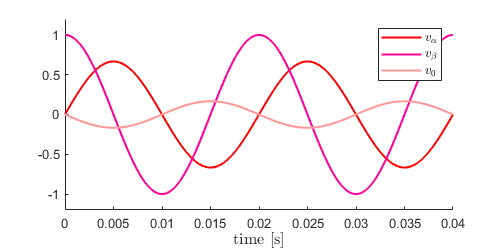


%% Plot de l'espai en forma cúbica

% Definició dels vèrtexs
verts3d = [-1 -1 -1; 
           -1 -1  1;
           -1  1 -1;
           -1  1  1;
            1 -1 -1;
            1 -1  1;
            1  1 -1;
            1  1  1];
        
centcara3d = [0  0  1;
              0  1  0;
              1  0  0;
              0  0 -1;
              0 -1  0;
             -1  0  0];
centcost3d = [1  0 -1;
              0  1 -1;
             -1  1  0;
             -1  0  1;
              0 -1  1;
              1 -1  0];
          
% Limits espai cúbic
f2 = figure(2);
set(f2, 'Position', [600 300 500 450]);
hold on;
plot3([verts3d(1,1) verts3d(2,1)],[verts3d(1,2) verts3d(2,2)],[verts3d(1,3) verts3d(2,3)],'LineWidth',1,'Color','k');
plot3([verts3d(2,1) verts3d(4,1)],[verts3d(2,2) verts3d(4,2)],[verts3d(2,3) verts3d(4,3)],'LineWidth',1,'Color','k');
plot3([verts3d(4,1) verts3d(3,1)],[verts3d(4,2) verts3d(3,2)],[verts3d(4,3) verts3d(3,3)],'LineWidth',1,'Color','k');
plot3([verts3d(3,1) verts3d(1,1)],[verts3d(3,2) verts3d(1,2)],[verts3d(3,3) verts3d(1,3)],'LineWidth',1,'Color','k');
plot3([verts3d(5,1) verts3d(6,1)],[verts3d(5,2) verts3d(6,2)],[verts3d(5,3) verts3d(6,3)],'LineWidth',1,'Color','k');
plot3([verts3d(6,1) verts3d(8,1)],[verts3d(6,2) verts3d(8,2)],[verts3d(6,3) verts3d(8,3)],'LineWidth',1,'Color','k');
plot3([verts3d(8,1) verts3d(7,1)],[verts3d(8,2) verts3d(7,2)],[verts3d(8,3) verts3d(7,3)],'LineWidth',1,'Color','k');
plot3([verts3d(7,1) verts3d(5,1)],[verts3d(7,2) verts3d(5,2)],[verts3d(7,3) verts3d(5,3)],'LineWidth',1,'Color','k');
plot3([verts3d(1,1) verts3d(5,1)],[verts3d(1,2) verts3d(5,2)],[verts3d(1,3) verts3d(5,3)],'LineWidth',1,'Color','k');
plot3([verts3d(2,1) verts3d(6,1)],[verts3d(2,2) verts3d(6,2)],[verts3d(2,3) verts3d(6,3)],'LineWidth',1,'Color','k');
plot3([verts3d(3,1) verts3d(7,1)],[verts3d(3,2) verts3d(7,2)],[verts3d(3,3) verts3d(7,3)],'LineWidth',1,'Color','k');
plot3([verts3d(4,1) verts3d(8,1)],[verts3d(4,2) verts3d(8,2)],[verts3d(4,3) verts3d(8,3)],'LineWidth',1,'Color','k');

limit = 1.2;
xlim([-limit limit]);
ylim([-limit limit]);
zlim([-limit limit]);
view(115,20);
axis square;
axis vis3d;
axis off;
view(110,10);

% Pla sense homopolar intersecat
plot3([centcost3d(1,1) centcost3d(2,1)],[centcost3d(1,2) centcost3d(2,2)],[centcost3d(1,3) centcost3d(2,3)],'LineWidth',1,'Color',[0.5 0.5 0.5]);
plot3([centcost3d(2,1) centcost3d(3,1)],[centcost3d(2,2) centcost3d(3,2)],[centcost3d(2,3) centcost3d(3,3)],'LineWidth',1,'Color',[0.5 0.5 0.5]);
plot3([centcost3d(3,1) centcost3d(4,1)],[centcost3d(3,2) centcost3d(4,2)],[centcost3d(3,3) centcost3d(4,3)],'LineWidth',1,'Color',[0.5 0.5 0.5]);
plot3([centcost3d(4,1) centcost3d(5,1)],[centcost3d(4,2) centcost3d(5,2)],[centcost3d(4,3) centcost3d(5,3)],'LineWidth',1,'Color',[0.5 0.5 0.5]);
plot3([centcost3d(5,1) centcost3d(6,1)],[centcost3d(5,2) centcost3d(6,2)],[centcost3d(5,3) centcost3d(6,3)],'LineWidth',1,'Color',[0.5 0.5 0.5]);
plot3([centcost3d(6,1) centcost3d(1,1)],[centcost3d(6,2) centcost3d(1,2)],[centcost3d(6,3) centcost3d(1,3)],'LineWidth',1,'Color',[0.5 0.5 0.5]);

% Plot vector espacial
plot3(va, vb, vc,'LineWidth',3,'Color','r');

% Eixos naturals
a = [1 0 0];
b = [0 1 0];
c = [0 0 1];
plot3([0 a(1)],[0 a(2)],[0 a(3)],'LineWidth',2,'Color','k');
plot3([0 b(1)],[0 b(2)],[0 b(3)],'LineWidth',2,'Color','k');
plot3([0 c(1)],[0 c(2)],[0 c(3)],'LineWidth',2,'Color','k');
text(a(1)+0.1,a(2)+0.0,a(3)+0.0,'a','FontSize',14,'Color','k');
text(b(1)+0.0,b(2)+0.1,b(3)+0.0,'b','FontSize',14,'Color','k');
text(c(1)+0.0,c(2)+0.0,c(3)+0.1,'c','FontSize',14,'Color','k');

% Eixos clarke (Mòdul invariant)
Clarke = (1/3) * [2 -1 -1;                  
                  0 -sqrt(3) sqrt(3);
                  1 1 1];
alpha = inv(Clarke) * a';
beta = inv(Clarke) * b';
gamma = inv(Clarke) * c';
                    
plot3([0 alpha(1)],[0 alpha(2)],[0 alpha(3)],'LineWidth',2,'Color','m');
plot3([0 beta(1)],[0 beta(2)],[0 beta(3)],'LineWidth',2,'Color','m');
plot3([0 gamma(1)],[0 gamma(2)],[0 gamma(3)],'LineWidth',2,'Color','m');
text(alpha(1)+0.1,alpha(2)+0.0,alpha(3)+0.0,'\alpha','FontSize',14,'Color','m');
text(beta(1)+0.0,beta(2)+0.1,beta(3)+0.0,'\beta','FontSize',14,'Color','m');
text(gamma(1)+0.0,gamma(2)+0.0,gamma(3)+0.1,'0','FontSize',14,'Color','m');

%% Plot temporal clarke

for i=1:1:201
    V_Clarke(i,:) = Clarke * [va(i); vb(i); vc(i)];
end
V_Clarke = V_Clarke';
valfa = V_Clarke(1,:);
vbeta = V_Clarke(2,:);
vgamma = V_Clarke(3,:);

f3 = figure(3);
set(f3, 'Position', [50 150 500 250]);
hold on;
plot(t,valfa,'LineWidth',1.5,'Color',[1 0 0]);
plot(t,vbeta,'LineWidth',1.5,'Color',[1 0 0.6]);
plot(t,vgamma,'LineWidth',1.5,'Color',[1 0.6 0.6]);
ylim([-1.2 1.2]);
l1 = legend('$v_{\alpha}$','$v_{\beta}$','$v_{0}$');
set(l1,'Interpreter','latex','FontSize',10,'Location','NorthEast');
xlabel('time [s]','Interpreter','latex','FontSize',12);

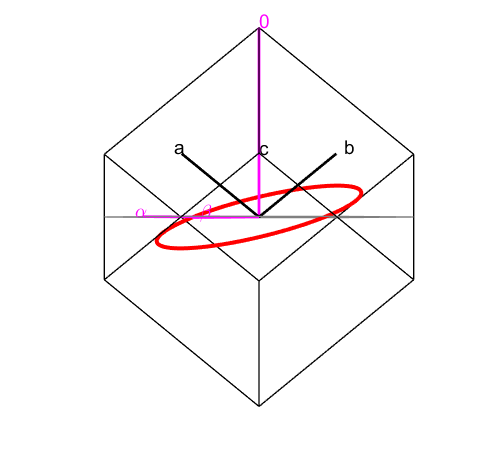



%% Vista ab
figure(2)
view(90,-90);
%% Vista bc
figure(2)
view(90,0);
%% Vista ac
figure(2)
view(0,0);
%% Vista alpha beta
figure(2)
view(135,35);
%% Vista alpha beta
figure(2)
view(135,-55);